clear all
clc
% eps_cut = [ones(1, 20),50*ones(1,20), 30*ones(1, 20), 1*ones(1, 20)];
eps_cut = [ones(1,30), 12.25*ones(1,20), ones(1, 30)];
% eps_cut = [1:40, 40:1];
eps = repmat(eps_cut, 1000, 1); % struct the simulated region
omega = 0.15;

Mode number: 1
kx : 0.502
Error of calculation: 0.000
Power: 1.000
Mode number: 2
kx : 0.426
Error of calculation: 0.000
Power: 1.000
Mode number: 3
kx : 0.268
Error of calculation: 0.000
Power: 1.000
Mode number: 4
kx : 0.145
Error of calculation: 0.000
Power: 1.000
Mode number: 5
kx : 0.128
Error of calculation: 0.000
Power: 1.000


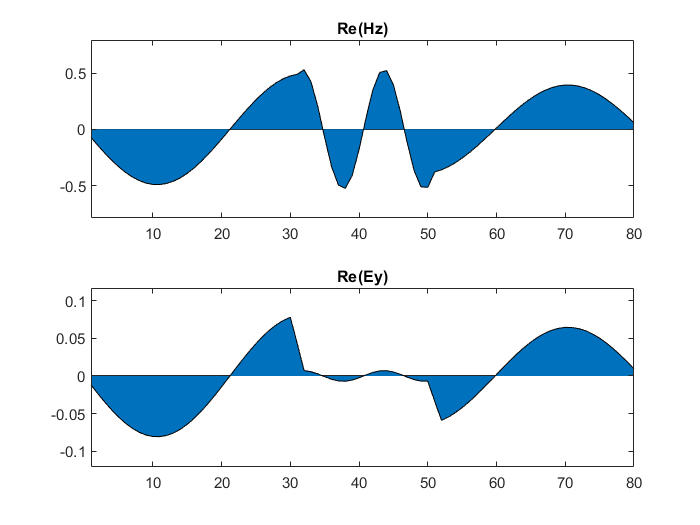

Mode number: 6
kx : 0.025
Error of calculation: 0.000
Power: 1.000


% Loop and reconstruct the full Hz field
for i = 1 : 6
[~, Hz, k] = wave_mode(eps_cut, omega, i, 'pos'); 
Hz = repmat(Hz, 1, 5000);

% construct the k term
k = ones(1, 5000) * exp(1i * k);
k = k .^ [1 : 5000];

Hz = k .* Hz;
mode(:, i) = Hz(:);
end

% test the orthogonality
ortho = mode' * mode;